# The kernel trick

This question uses a subset of the iris data - only the sepal widths and sepal lengths for the versicolor and virginica classes:

clear all;
load('binary.mat', 'examples', 'labels');

This question is about training and visualising Support Vector Machines (SVMs) that use the kernel trick to produce nonlinear boundaries. You should use the whole dataset (without splitting) for training. Note that the dataset has already been z-score stadardised.

Marks are available for:

- An appropriate call to train an SVM on the whole dataset, using the kernel trick with a Radial Basis Function (RBF) kernel [3 marks]

- An appropriate call to train a *second* SVM on the whole dataset, using the kernel trick with an RBF kernel and a KernelScale of 0.4 [3 marks]

- Extending the `visualiseSVM()` function to give a helpful visualisation of any 2D model trained by the `fitcsvm()` function (the visualisation should at least include the decision boundary and the original training data) [8 marks]

- Using the `visualiseSVM()` function you have developed to produce a visualisation of each of the two SVMs you have trained [2 marks]

- Commenting your code to explain the steps you are taking [4 marks]

[Total: 20 marks]

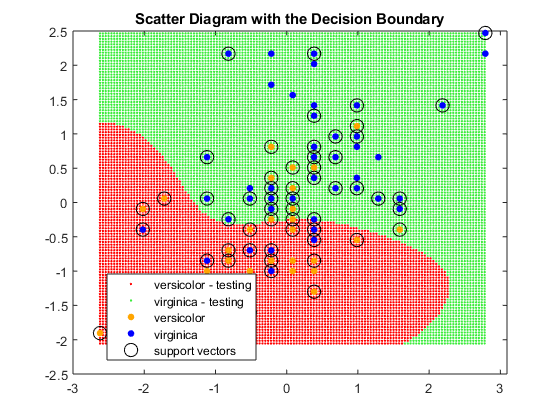

% add as many lines of code as you need below:

%1.
m1 = fitcsvm(examples, labels, 'KernelFunction', 'rbf');

%2.
m2 = fitcsvm(examples, labels, 'KernelFunction', 'rbf', 'KernelScale', 0.4);

%4.
visualiseSVM(m1);

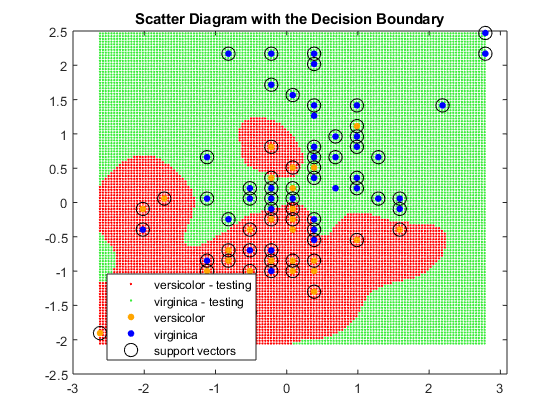

visualiseSVM(m2);

function visualiseSVM(m)

% Hint: for any model, m, trained with fitcsvm(),
% you can access the data used to train it with:

% Add as many lines of code as you need below:
%3.

d = 0.04;
grid = [];
examples = table2array(m.X);
for i=min(examples(:,1)):d:max(examples(:, 1))
    for j=min(examples(:,2)):d:max(examples(:, 2))
        newRow = [i j];
        grid = [grid; newRow];
    end
end

predictions = predict(m,grid); 

figure;

hexColours = ['#FF0000';'#3CEC3C';'#ffa500';'#0000FF'];
cmap = hex2rgb(hexColours);
gscatter(grid(:, 1), grid(:, 2), predictions, cmap(1:2, :));
hold on;
gscatter(examples(:,1),examples(:,2),m.Y, cmap(3:4, :));
plot(examples(m.IsSupportVector,1),...
    examples(m.IsSupportVector,2),'ko','MarkerSize',10);


title('Scatter Diagram with the Decision Boundary')
hold off
legend({'versicolor - testing','virginica - testing','versicolor','virginica','support vectors'}, 'Location','Best')


end